## Run Simulation

Click **Run** to create an  `autoblks.pwr.PlantInfo` object that analyzes the model energy consumption. Use the `PwrUnits` and `EnrgyUnits` properties to set the units.

After you run the simulation, the live script provides the energy summary.  You can use the results to analyze energy and power losses at the component and system level. For more information, see [Explore the Hybrid Electric Vehicle Multimode Reference Application](matlab:helpview([docroot,'/toolbox/autoblks/helptargets.map'],'hybrid_refapp')).

SysName = 'HevMmReferenceApplication';
VehPwrAnalysis = autoblks.pwr.PlantInfo(SysName);
VehPwrAnalysis.PwrUnits = 'kW';
VehPwrAnalysis.EnrgyUnits = 'MJ';

Use `run` method to turn on logging, run simulation, and add logged data to the object.

VehPwrAnalysis.run;

### 启动串行模型引用仿真编译
### BattHevMm 的模型引用仿真目标是最新的。


### Successfully updated the model reference simulation target for: DrivetrainHevMm
### GenMapped 的模型引用仿真目标是最新的。
### MotMapped 的模型引用仿真目标是最新的。
### SiEngineController 的模型引用仿真目标是最新的。
### SiMappedEngine 的模型引用仿真目标是最新的。
### BMS_Out 的模型引用仿真目标是最新的。
### Balancing_Logic 的模型引用仿真目标是最新的。
### CurrPowerLimCalc 的模型引用仿真目标是最新的。
### SOC_Estimation 的模型引用仿真目标是最新的。
### State_Machine 的模型引用仿真目标是最新的。
### HevMmPowertrainController 的模型引用仿真目标是最新的。
### BMS_Software 的模型引用仿真目标是最新的。

编译摘要

编译的仿真目标:

模型               操作        重新编译原因                     
DrivetrainHevMm  生成和编译的代码  模型或库 DrivetrainHevMm 已更改。  

编译了 1 个模型，共 13 个模型(12 个模型已经是最新的)
编译持续时间: 0h 1m 19.585s


## Overall Summary

Display the final energy values for each subsystem.

VehPwrAnalysis.dispSysSummary

               System Name                 Efficiency    Energy Loss (MJ)    Energy Input (MJ)    Energy Output (MJ)    Energy Stored (MJ)  
--------------------------------------------------------------------------------------------------------------------------------------------
HevMmReferenceApplication                       0.196               -69.2                   68                     0                  1.67  
  Passenger Car                                 0.196               -69.2                   68                     0                  1.67  
    Drivetrain                                   1.06                 -25                 29.3                 -27.7                  3.68  


Write summary to spreadsheet.

VehPwrAnalysis.xlsSysSummary(fullfile(fileparts(which('GenerateEnergyReport')), 'EnergySummary.xlsx'))

## Engine Plant Summary

EngSysName = 'HevMmReferenceApplication/Passenger Car/Engine';
EngPwrAnalysis = VehPwrAnalysis.findChildSys(EngSysName);
EngPwrAnalysis.dispSignalSummary;

 
HevMmReferenceApplication/Passenger Car/Engine
Average Efficiency = 0.00
 
       Signal         Energy (MJ)  
-----------------------------------
Inputs                       64.2  
  Not transferred            64.2  
Outputs                         0  
Losses                      -39.9  
Stored                          0  


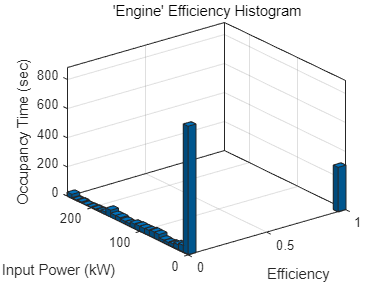

EngPwrAnalysis.histogramEff;

## Electric Plant Summary

ElecSysName = 'HevMmReferenceApplication/Passenger Car/Electric Plant';
ElecPwrAnalysis = VehPwrAnalysis.findChildSys(ElecSysName);
ElecPwrAnalysis.dispSignalSummary;

## Drivetrain Plant Summary

DrvtrnSysName = 'HevMmReferenceApplication/Passenger Car/Drivetrain';
DrvtrnPwrAnalysis = VehPwrAnalysis.findChildSys(DrvtrnSysName);
DrvtrnPwrAnalysis.dispSignalSummary;

## SDI Plots

VehPwrAnalysis.sdiSummary({EngSysName, ElecSysName, DrvtrnSysName})